clear;
global SAVE_EXT;
global SAVE_DIR;
SAVE_EXT = "png";% figure saving conf (png, eps, etc...)
SAVE_DIR = "lab1/tex/images/";
mkdir(SAVE_DIR)

## Task 1

T = 0.2;
K_CO = 5.7;

function task_1(exp_name)
    global SAVE_EXT;
    global SAVE_DIR;
    sim_res = sim("lab1/task1.slx", 4);
    clf;
    title("System state")
    hold on
    plot(sim_res.x.time, sim_res.x.data(:,1), 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-')
    grid on
    hold off
    exportgraphics(gcf, SAVE_DIR + exp_name + "_state." + SAVE_EXT)
end

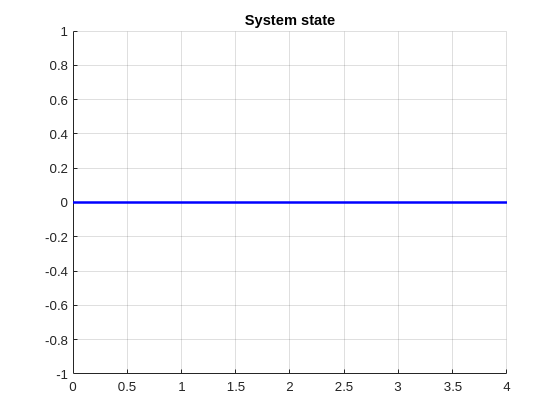

K_FB = 0.0;
task_1("task1_b__neutral")

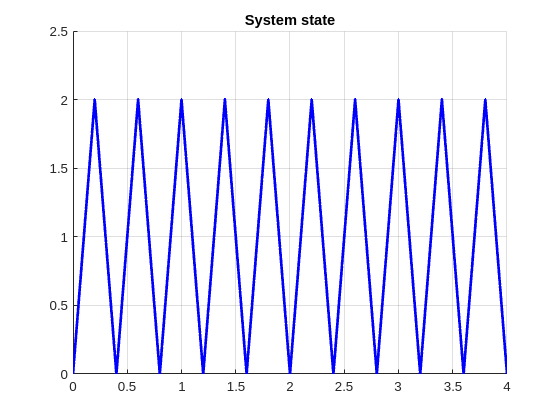

K_FB = 100/57;
task_1("task1_b__oscill")

K_FB = 2 / (T * K_CO);
task_1("task1_d__max")

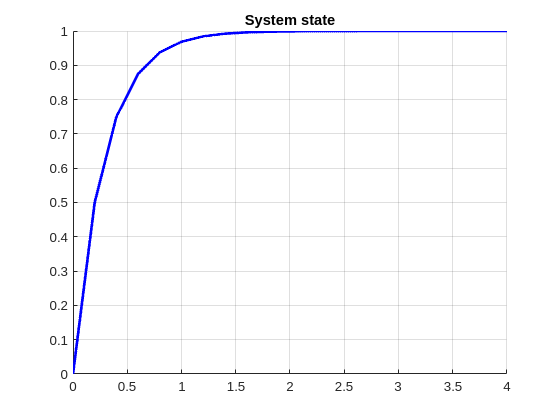

K_FB = 1 / (T * K_CO)* 0.5;
task_1("task1_d__no")

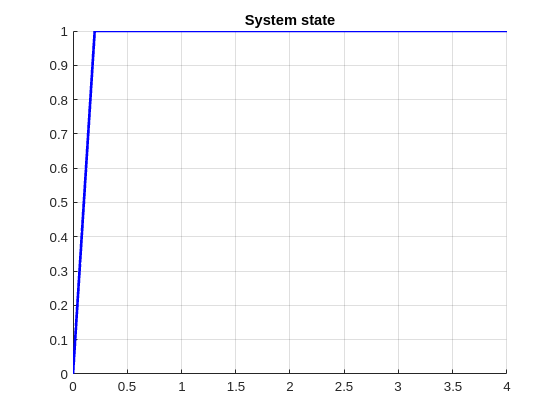

K_FB = 1 / (T * K_CO);
task_1("task1_e__optim")

## Task 2

A_n = [0 1; 0 0];
B_n = [0; 1];
C_n = [1 0];
D_n = 0;
cont_sys = ss(A_n, B_n, C_n, D_n)

cont_sys =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties

discr_sys = c2d(cont_sys, T)

discr_sys =
 
  A = 
        x1   x2
   x1    1  0.2
   x2    0    1
 
  B = 
         u1
   x1  0.02
   x2   0.2
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.2 seconds
Discrete-time state-space model.


function task_2(exp_name)
    global SAVE_EXT;
    global SAVE_DIR;
    sim_res = sim("lab1/task2.slx", 15);
    h = figure();
    title("System state")
    hold on
    plot(sim_res.x.time, sim_res.x.data(:,1), 'LineWidth', 1, 'Color', 'blue', 'LineStyle', '-')
    plot(sim_res.x.time, sim_res.x.data(:,2), 'LineWidth', 1, 'Color', 'red', 'LineStyle', '-')
    legend(["$y$", "$\dot{y}$"],Interpreter="latex")
    grid on
    hold off
    exportgraphics(gcf, SAVE_DIR + exp_name + "_state." + SAVE_EXT)
end

K =     2.2500    4.7750


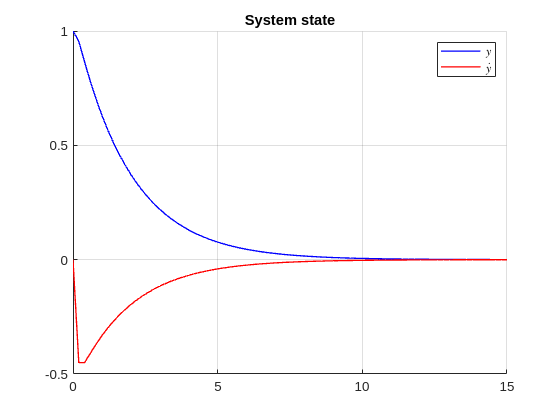

K =    49.5000    9.5500


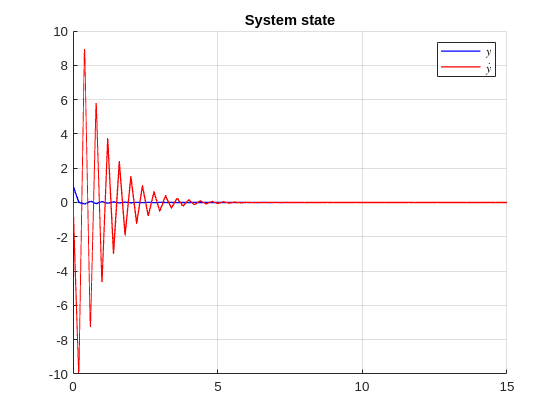

K =    20.0000    7.0000


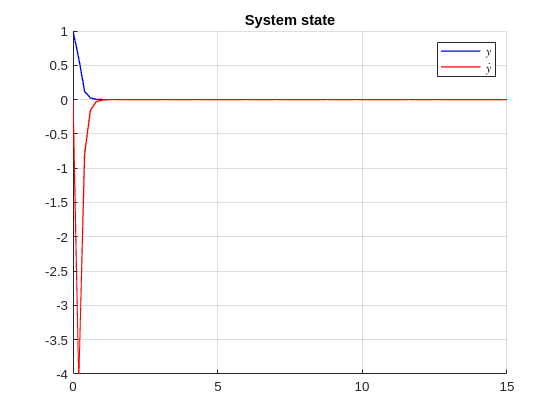

K =    41.0000    5.9000


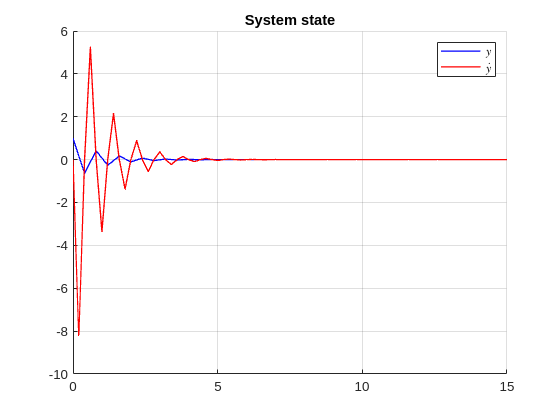

K =    56.2500    6.3750


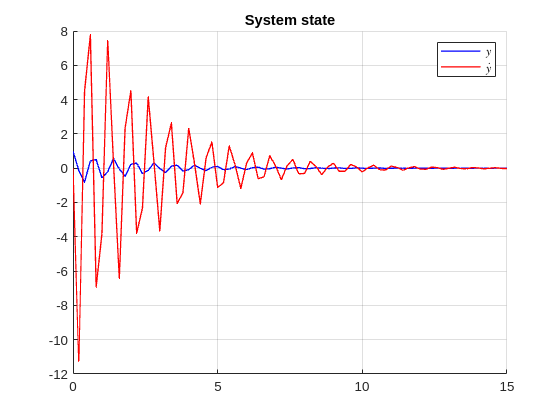

des_roots = [
    0.9 0.1;
    -0.1 -0.8;
    0.2 0;
    0.8i -0.8i;
    -0.2+0.9i -0.2-0.9i
];

for i = 1:5
    K = place(discr_sys.A,discr_sys.B, des_roots(i,:)')
    task_2("task2_d__"+string(i))
end

## Task 3

A_m = 9.8;
omega = 0.18;
sub_1_gen = [0 omega; -omega 0]

sub_1_gen =          0    0.1800
   -0.1800         0


sub_2_gen = [-5 6 0 0; -6 -5 0 0; 0 0 0 1; 0 0 0 0]

sub_2_gen =     -5     6     0     0
    -6    -5     0     0
     0     0     0     1
     0     0     0     0


### subtask 1

T_1 = 1;
discr_sys_1 = ss([0 1; -1 2*cos(T_1*omega)], [0; 0], [1, 0], 0, T_1);
init_1 = [0; A_m *sin(omega*T_1)];

### subtask 2

T_2 = 0.25;
discr_sys_2 = ss(sub_2_gen, [0; 0; 0; 0], [1 0 0.03 0], 0);
init_2 = [sin(2.5); cos(2.5); 0; 1]

init_2 =     0.5985
   -0.8011
         0
    1.0000


discr_sys_2 = c2d(discr_sys_2, T_2)

discr_sys_2 =
 
  A = 
            x1       x2       x3       x4
   x1  0.02027   0.2858        0        0
   x2  -0.2858  0.02027        0        0
   x3        0        0        1     0.25
   x4        0        0        0        1
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
 
  C = 
         x1    x2    x3    x4
   y1     1     0  0.03     0
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.


### Modeling

function task_3(exp_name)
    global SAVE_EXT;
    global SAVE_DIR;
    sim_res = sim("lab1/task3.slx", 20);
    h = figure();
    title("System state")
    hold on
    plot(sim_res.g_1_cont.time, sim_res.g_1_cont.data(:,1), 'LineWidth', 1, 'Color', 'blue', 'LineStyle', '-')
    plot(sim_res.g_1_discr.time, sim_res.g_1_discr.data(:,1), 'LineWidth', 1, 'Color', 'red', 'LineStyle', '--')
    legend(["$g(t)$", "$g(kT)$"],Interpreter="latex")
    grid on
    hold off
    exportgraphics(gcf, SAVE_DIR + exp_name + "_state_1." + SAVE_EXT)

    h = figure();
    title("System state")
    hold on
    plot(sim_res.g_2_cont.time, sim_res.g_2_cont.data(:,1), 'LineWidth', 1, 'Color', 'blue', 'LineStyle', '-')
    plot(sim_res.g_2_discr.time, sim_res.g_2_discr.data(:,1), 'LineWidth', 1, 'Color', 'red', 'LineStyle', '--')
    legend(["$g(t)$", "$g(kT)$"],Interpreter="latex")
    grid on
    hold off
    exportgraphics(gcf, SAVE_DIR + exp_name + "_state_2." + SAVE_EXT)
end

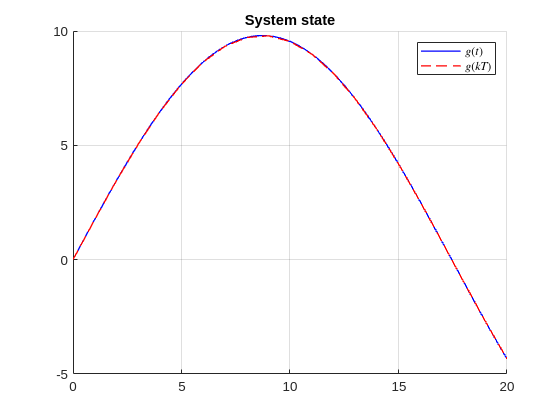

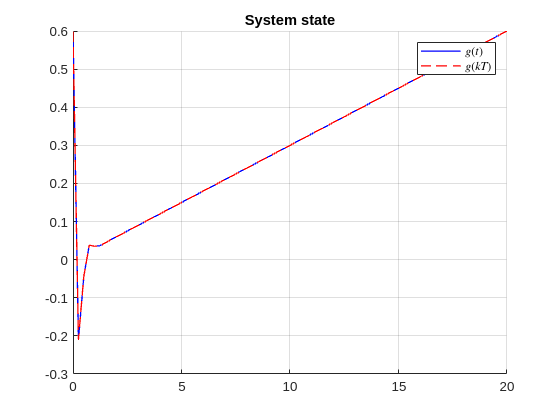

task_3("task3")